# Canard Roll Control Model

### Overview

This script will serve as the primary model for the controls simulation. It will feature a cascaded PID control, with the PID values being gain scheduled based on a function of velocity V.

### State Values

Vx = Velocity in the X direction (Up) (m/s)

p = roll rate (deg/s)

x = altitude (m)

ix = moment of intertia about the x axis (kg/m^2)

m = mass (kg)

phi = current roll heading (deg)

dt = time step value

### Controller Values

Kp_P = Primary Proportinal coefficient as functino of Vx

Ki_P = Primary Integral coefficient as function of Vx

Kd_P = Primary derivative coefficient as function of Vx

Kp_S = Secondary proportional coefficient (not function of V)

Ki_S = Secondary integral coefficient (not function of V)

Kd_S = Seconday derivative coefficient ( not function of V)

### Control Values

can_theta = current angle of the canards (deg)

can_wmax = fastest control angular speed of canard (deg/s)

can_M = Moment created by canard (function of can_theta, Vx, and x)

- should make a helper function for this

alpha = can_M / I = angular acceleration (deg/s^2)

# Simulation Theory

If our goal is to control the Roll of the rocket, we need to consider in our simulation that we cannot simply read the heading of the rocket from our sensors. To compensate for this our control loop will need to manually integrate the roll rate to gain the heading. we should initially just try and controll roll rate before moving onto an alogorithim that can control the heading.

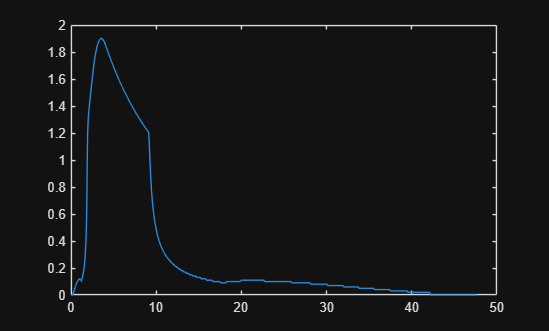

% |----- Inputs setup -----|
%[ork_filename, pathname] = uigetfile({'*.csv'});
%orkFullFile = fullfile(pathname, ork_filename);

if isequal(ork_filename, 0)
    error('No ORK simulation file was selected.');
end

ork_data = readtable('Sim-Data.csv', VariableNamingRule="preserve");    %| Import data from an ORK sim csv

orkTime = ork_data.("# Time (s)");
x_ork = ork_data.("Altitude (m)");
Vx_ork = ork_data.("Vertical velocity (m/s)");
Ix_ork = ork_data.("Rotational moment of inertia (kg·m²)");
m_ork = ork_data.("Mass (kg)");
p_ork = ork_data.("Roll rate (r/s)"); %| This is a refernce array, once the controls loop starts it will not be used
p_ork = fillmissing(p_ork, 'constant', 0);
phi_ork = cumtrapz(orkTime, p_ork);   %| This too


%| Time

[orkTimeU, ia] = unique(orkTime,'stable');

t_step = 1e-3;
t = 0:t_step:orkTime(end);
x = interp1(orkTimeU, x_ork(ia), t);
Vx = interp1(orkTimeU, Vx_ork(ia), t);
Ix = interp1(orkTimeU, Ix_ork(ia), t);
m = interp1(orkTimeU, m_ork(ia), t);
p = interp1(orkTimeU, p_ork(ia), t);
phi = interp1(orkTimeU, phi_ork(ia), t);


% |------ CONTROLLER VALUES ------ |

Kp_P = 20;  %|------------------------
Ki_P = 0.5; %| Primary Loop PID values
Kd_P = 0.1; %|------------------------

Kp_S = 20;  %|------------------------
Ki_S = 0.5; %| Secondary Loop PID Values
Kd_S = 0.1; %|------------------------

p_target = 0;

% |------ System Dynamics Inputs ------ |

L = 3;           %| (N) Lift created by canards **UPDATE TO ARRAY ONCE CFD IS DONE
dist = 0.2;      %| (m) moment arm/distance from canard CP to the body x axis**
can_theta = 0;   %| (deg) current canard angle
can_maxw = 1740; %| (deg/s) Max servo speed (change for test different servos)
can_maxt = 10;   %| (deg) Maximum allowed servo angle